clc;
clear all;
close all;
tic

Load data from config file using load_config function

config = load_config('conf_file')


config =

  dictionary (string ⟼ cell) with 8 entries:

    "type"     ⟼ {'zf'}
    "num_Tx"   ⟼ {'2'}
    "num_Rx"   ⟼ {'2'}
    "M"        ⟼ {'16'}
    "num_symb" ⟼ {'15000'}
    "points"   ⟼ {'10'}
    "ebn0_min" ⟼ {'8'}
    "ebn0_max" ⟼ {'18'}




num_Tx = str2num(config{'num_Tx'});
num_Rx = str2num(config{'num_Rx'});
eb_n0_min = str2num(config{'ebn0_min'});
eb_n0_max = str2num(config{'ebn0_max'});
points = str2num(config{'points'});
mod_Order = str2num(config{'M'});
num_symbols = str2num(config{'num_symb'});

## Leggi il contenuto del file output e plotta i risultati

TO DO: 

- calcolare il C.I. delle righe di ciascuna configurazione

- sistemare colori legenda

Apri, se esistono, tutti i file con la stessa configurazione attualmente specificata nel config file

% Read Zero forcing data
file_zf = strcat('output_', 'zf', '_', config{'num_Tx'}, '_', config{'num_Rx'}, '_', config{'ebn0_min'}, '_', ...
                    config{'ebn0_max'}, '_', config{'points'}, '_', config{'M'}, '_', config{'num_symb'}, '.txt');
if isfile(file_zf)
    ber_zf = readmatrix(file_zf);
    fclose('all');
end

% Read MMSE data
file_mmse = strcat('output_', 'mmse', '_', config{'num_Tx'}, '_', config{'num_Rx'}, '_', config{'ebn0_min'}, '_', ...
                    config{'ebn0_max'}, '_', config{'points'}, '_', config{'M'}, '_', config{'num_symb'}, '.txt');
if isfile(file_mmse)
    ber_mmse = readmatrix(file_mmse);
    fclose('all');
end

% Read vblast data
file_vblast = strcat('output_', 'vblast', '_', config{'num_Tx'}, '_', config{'num_Rx'}, '_', config{'ebn0_min'}, '_', ...
                    config{'ebn0_max'}, '_', config{'points'}, '_', config{'M'}, '_', config{'num_symb'}, '.txt');
if isfile(file_vblast)
    ber_vblast = readmatrix(file_vblast);
    fclose('all');
end

Plot the figures

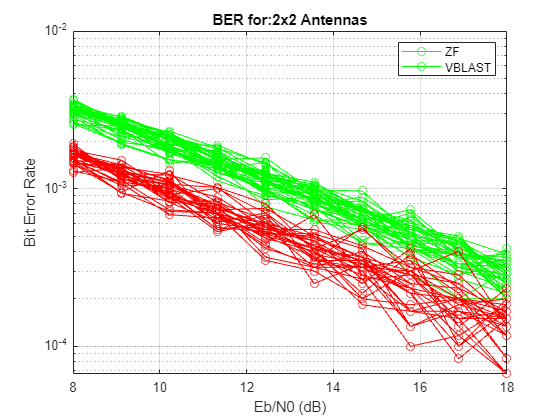

fig1 = figure;
leg = strings([1,3]);

% Plot zf if exists
if exist("ber_zf", "var")
    eb_n0 = linspace(eb_n0_min, eb_n0_max, length(ber_zf(1, :)));
    semilogy(eb_n0, ber_zf, 'g-o');
    leg(1,1) = "ZF";
    hold on;
end

% Plot mmse if exists
if exist("ber_mmse", "var")
    eb_n0 = linspace(eb_n0_min, eb_n0_max, length(ber_mmse(1, :)));
    semilogy(eb_n0, ber_mmse, 'b-o');
    leg(1,2) = "MMSE";
    hold on;
end

% Plot vblast if exists
if exist("ber_vblast", "var")
    eb_n0 = linspace(eb_n0_min, eb_n0_max, length(ber_vblast(1, :)));
    semilogy(eb_n0, ber_vblast, 'r-o');
    leg(1,3) = "VBLAST";
end

hold off;
legend(leg(1), leg(2), leg(3))
title({ strcat('BER for: ', num2str(num_Tx), 'x' , num2str(num_Rx), ' Antennas')})
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Print execution time

toc

Elapsed time is 1.968138 seconds.
